По бесконечно длинному цилиндрическому проводнику радиуса *а *протекает постоянный ток *I*, равномерно распределенный по площади поперечного сечения. Построить зависимости напряженности и индукции магнитного поля *H(r) *и *B(r)*, создаваемого этим  током в однородной среде с *μ**r *= 1. Исходные данные: *I*[A] = 0,1·N+M, *a*[мм] = 2+0,1·N.

- **ДАНО**

M = 5; N = 12;
mr = 1

mr = 1

I = 0.1*N + M

I = 6.2000

a = 2 + 0.1*N

a = 3.2000

- **НАЙТИ**

*H(r) - ?*

*B(r) - ?*

- **РЕШЕНИЕ**

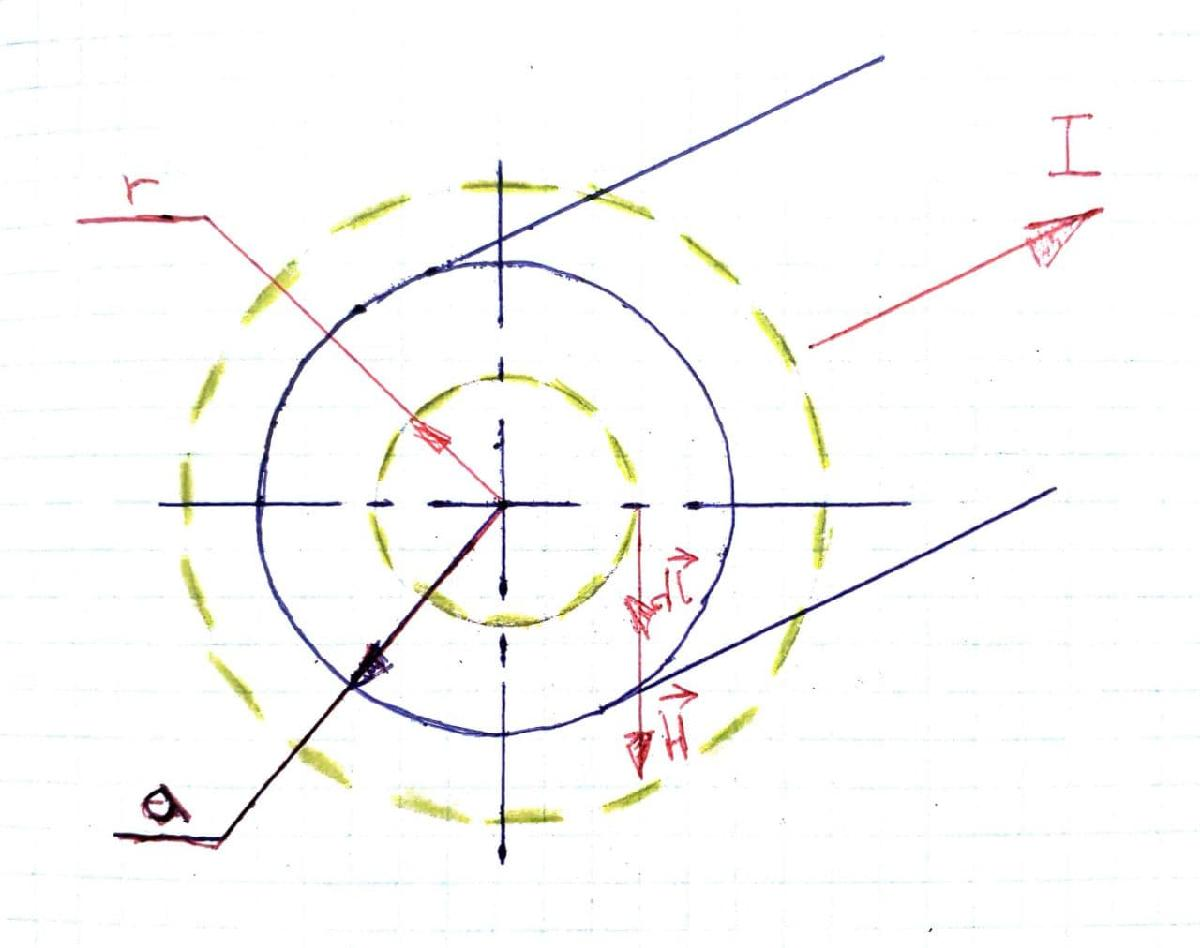

Учтем первое уравнение Максвелла 

$\oint_L \overrightarrow{H} d\overrightarrow{l} =\int_S \left(\overrightarrow{j} +\frac{\partial }{\partial t}\overrightarrow{D} \right)d\overrightarrow{S}$,

Пусть по бесконечно длинному цилиндрическому проводу радиуса *R* про­текает по­стоянный ток I . Возьмем окружность за контур L т.к. она обладает осевой симметрией(поле по модулю будет одинаковым). А так же центр совпадает с центром поперечного сечения в результате 

$H=const$.

Так как $\vec{H}$напрвлен по касательной, то при выборе такого контура $\vec{H} ||\vec{D} \;$. Тогда из первого уравнения Максвелла следует,

что $\overrightarrow{H} d\overrightarrow{l} =Hdl$ и $\oint_L \overrightarrow{H} d\overrightarrow{l} =\oint_L Hdl$, тогда

$\oint_L \overrightarrow{H} d\overrightarrow{l} =\oint_L Hdl=H\left(r\right)\oint_L dl=H\left(r\right)2\pi r$,

где $H\left(r\right)$ - не зависит от L. И так теперь мы имеем два случая:

- $\frac{\partial }{\partial t}D=0$, так как ток постоянный и поле соответственно тоже постоянно.

- $\int_S \vec{J} d\vec{S} =JdS,\;\mathrm{т}\ldotp \mathrm{к}\ldotp \vec{J} ||d\vec{S}$, то плотность тока считается постоянной, так как ток постоянный и распределенно равномерно, то ток протекает $\perp$попереченому сечению провода. Тогда $J=\frac{I}{S\left(a\right)}=\frac{I}{\pi a^2 }$.

Для случая 1 $r\le a$, тогда 

$\int_S \vec{J} d\vec{S} \;=\;J\int_S dS*\frac{I}{\pi a^2 }\Longrightarrow \pi r^2 =\frac{I}{a^2 }r^2$,

тогда из первого уравнения Максвелла следует, что 

$H\left(r\right)2\pi r=\frac{I}{a^2 }r^2 \Longrightarrow H\left(r\right)=\frac{Ir}{2\pi a^2 }$,

а так же, так как $\vec{B} =\mu \left(r\right)\vec{H}$, то

$B\left(r\right)=\frac{Ir\mu \left(r\right)}{2\pi a^2 }$.

Тогда для случая 2 $r\ge a$, будет

 $\int_S \overrightarrow{J} d\overrightarrow{S} =I$,

тогда 

$H\left(r\right)2\pi r=I\Longrightarrow H\left(r\right)=\frac{I}{2\pi r}\;$,

 а так же, так как $\overrightarrow{B} =\mu \left(r\right)\overrightarrow{H}$, то

$B\left(r\right)=\frac{I\mu \left(r\right)}{2\pi r}$.

Итак подведем итог

$H=\frac{I}{2\pi r}\;$при r > R, $H=\frac{Ir}{2\pi a^2 }$ при r < R , и

$B=\frac{I\mu \left(r\right)}{2\pi r}$ при r > R, $B=\frac{Ir\mu \left(r\right)}{2\pi a^2 }$ при r < R.

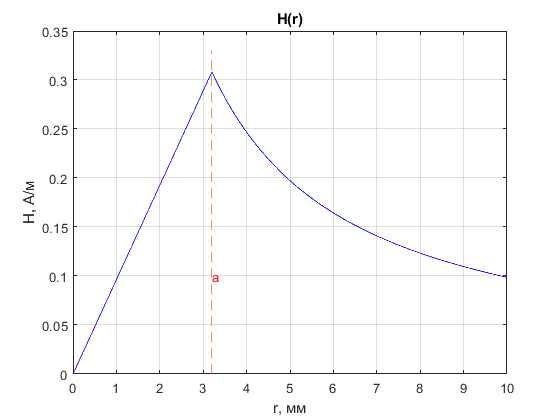

cla reset;
[H, r] = H_graph(I, a, 1);
plot(r, H, "Color","blue");
hold on;
plot([a a], [0 0.33], '--');
hold off;
xlabel("r, мм"); 
ylabel("H, A/м"); 
title("H(r)");  
text(a, 0.1,'a', 'Color','red'); 
grid on;
saveas(gcf, "H_gr_true.png") 

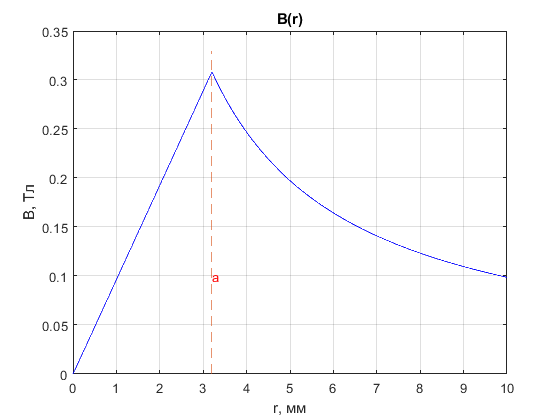


[B, r] = B_graph(I, a, mr, 1);
plot(r, B, "Color","blue");
hold on;
plot([a a], [0 0.33], '--');
hold off;
xlabel("r, мм");
ylabel("B, Тл");
title("B(r)");
text(a, 0.1,'a', 'Color','red');
grid on;
saveas(gcf, "B_gr_true.png")

$H=\frac{I}{2\pi r}\;$при r > R, $H=\frac{\textrm{Ir}}{2\pi a^2 }$ при r < R

function [H, r] = H_graph(I, a, n)
    r = linspace(0, 10, 1001);
    H = zeros(1, 1001); 
    for v = 0.0:0.01:10
        if v <= a
            H(n) = (I*v)/(2*pi*a^2); 
            n = n + 1;
        else
            H(n) = I/(2*pi*v);
            n = n + 1;
        end
    end 
end

$B=\frac{I\mu \left(r\right)}{2\pi r}$ при r > R, $B=\frac{\textrm{Ir}\mu \left(r\right)}{2\pi a^2 }$ при r < R

function [B, r] = B_graph(I, a, mr, n)
    r = linspace(0, 10, 1001);
    B = zeros(1, 1001);
    for v = 0.0:0.01:10
        if v <= a
            B(n) = (I*v*mr)/(2*pi*(a^2));
            n = n + 1;
        else 
            B(n) = (I*mr)/(2*pi*v);
            n = n + 1;
        end
    end
end